clear;
clc;

#### 一、描绘下列各函数的波形（连续信号时间间隔为0.001），其中第(4)小题用subplot命令分别用plot、stem绘制出图形

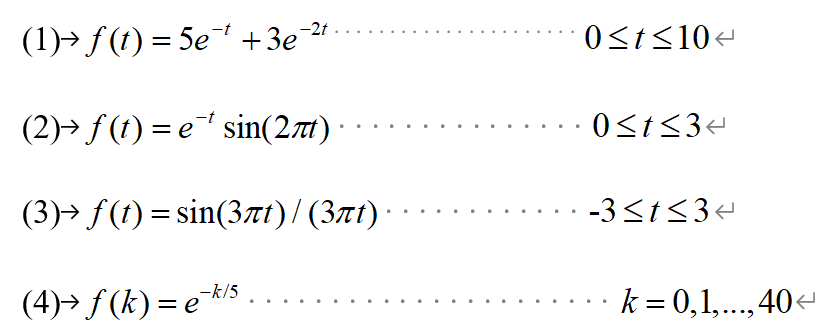

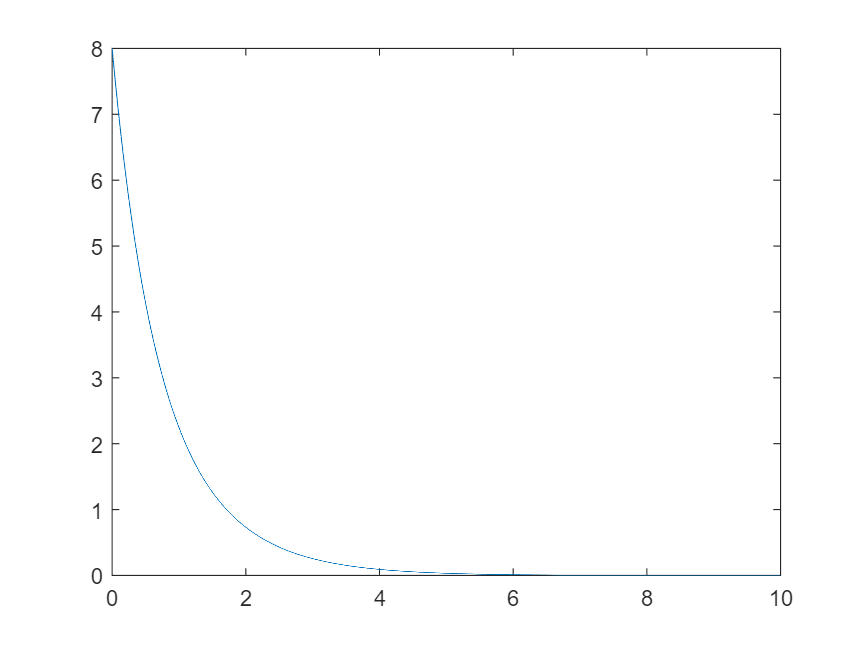

%(1)
t1=0:0.001:10;
f1=5.*exp(-t1)+3.*exp(-2*t1);
figure(1);
plot(t1,f1);

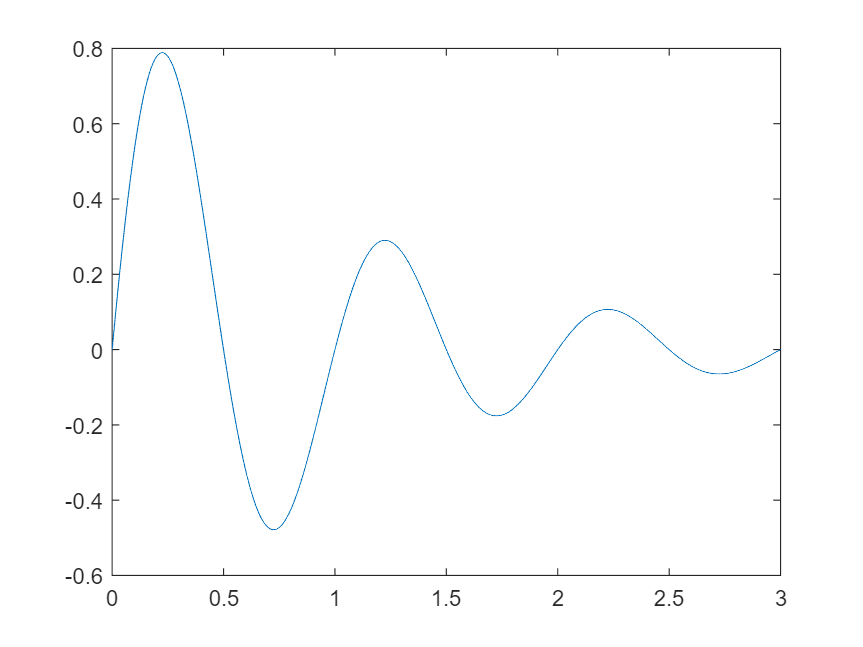

%(2)
t2=0:0.001:3;
f2=exp(-t2).*sin(2*pi*t2);
figure(2);
plot(t2,f2);

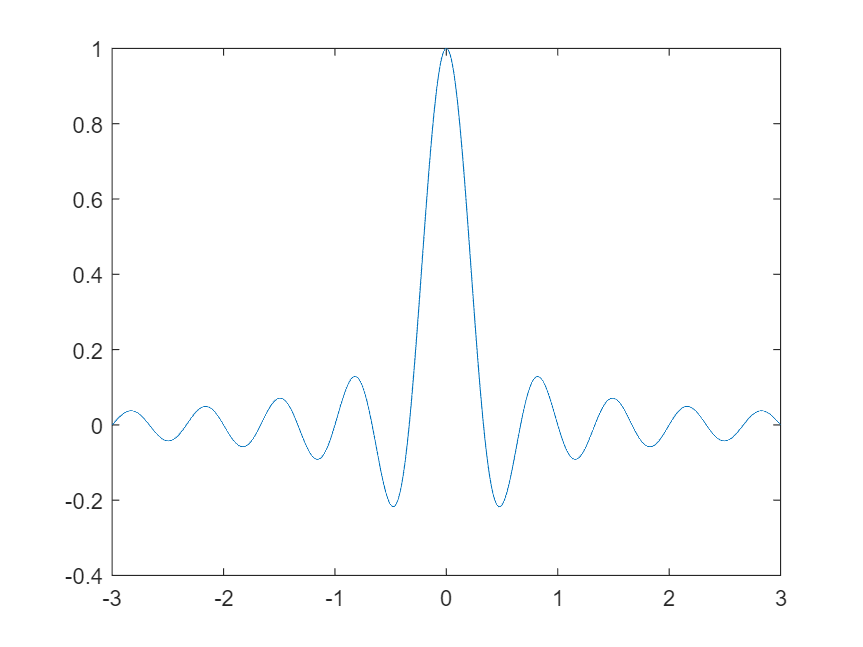

%(3)
t3=-3:0.001:3;
f3=sin(3*pi*t3)./(3*pi*t3);
figure(3);
plot(t3,f3);

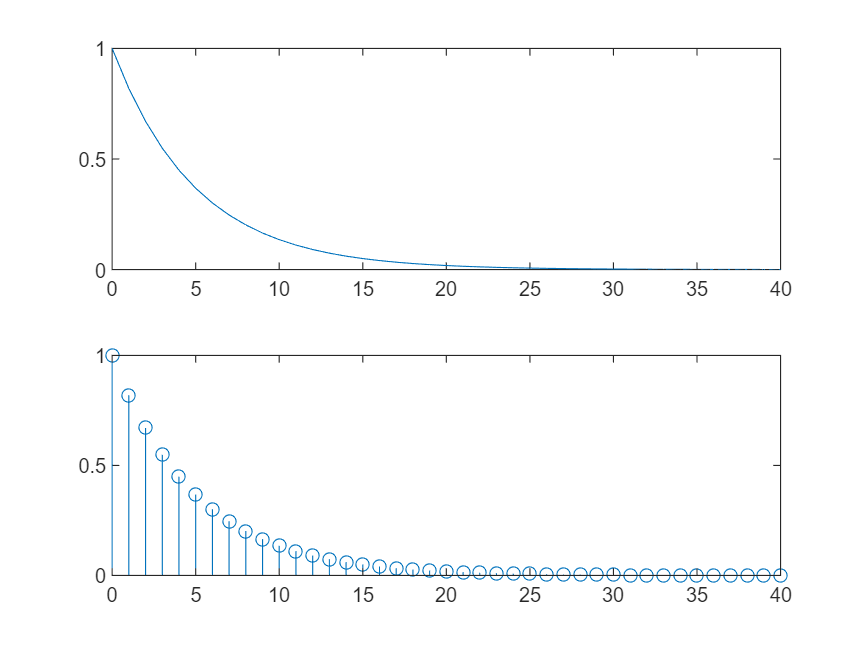

%(4)
k=0:1:40;
f4=exp(-k./5);
figure(4);
subplot(2,1,1);
plot(k,f4);
subplot(2,1,2);
stem(k,f4);

clear;
clc;

#### 二、利用MATLAB求解线性方程组

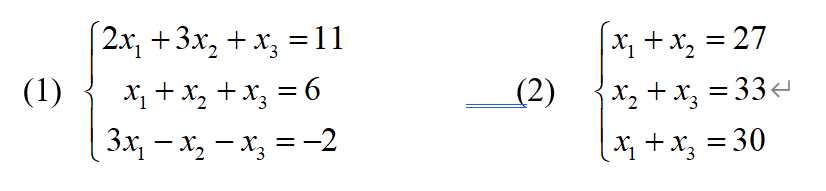

%(1)
A1=[2,3,1;1,1,1;3,-1,-1];
b1=[11;6;-2];
x1=inv(A1)*b1;
disp("方程组（1）的解：");

方程组（1）的解：


disp(x1);

    1.0000
    2.0000
    3.0000



%(2)
A2=[1,1,0;0,1,1;1,0,1];
b2=[27;33;30];
x2=inv(A2)*b2;
disp("方程组（2）的解：");

方程组（2）的解：


disp(x2);

    12
    15
    18



clear;
clc;

#### 三、绘制出以下离散信号的波形，k的范围均为[-40 40]

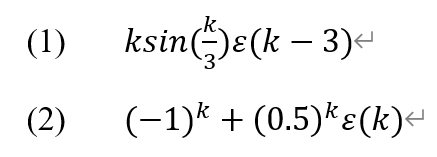

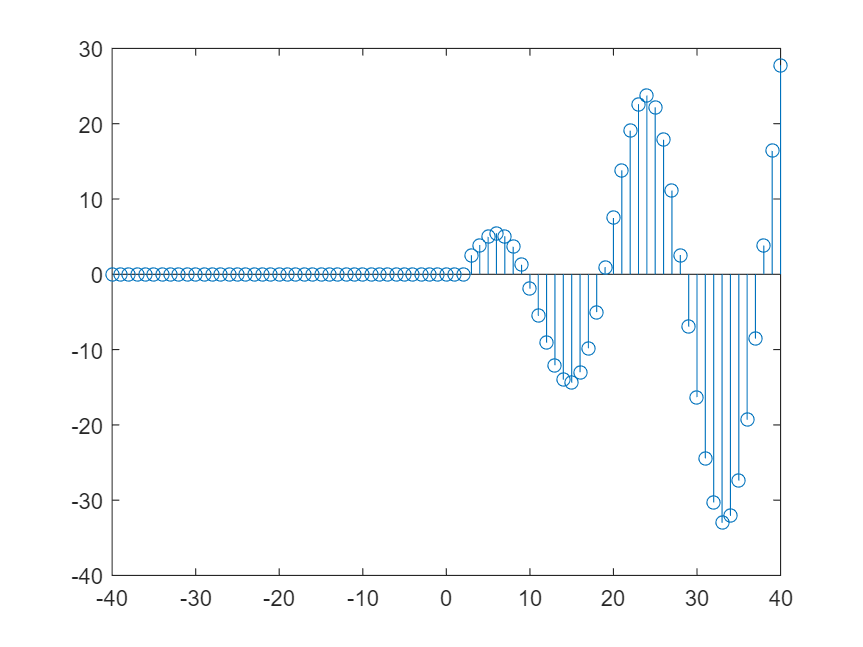

k=-40:1:40;
%(1)
z1=k.*sin(k./3).*stepfun(k,3);%stepfun第二个参数是起始位置
figure(5)
stem(k,z1)

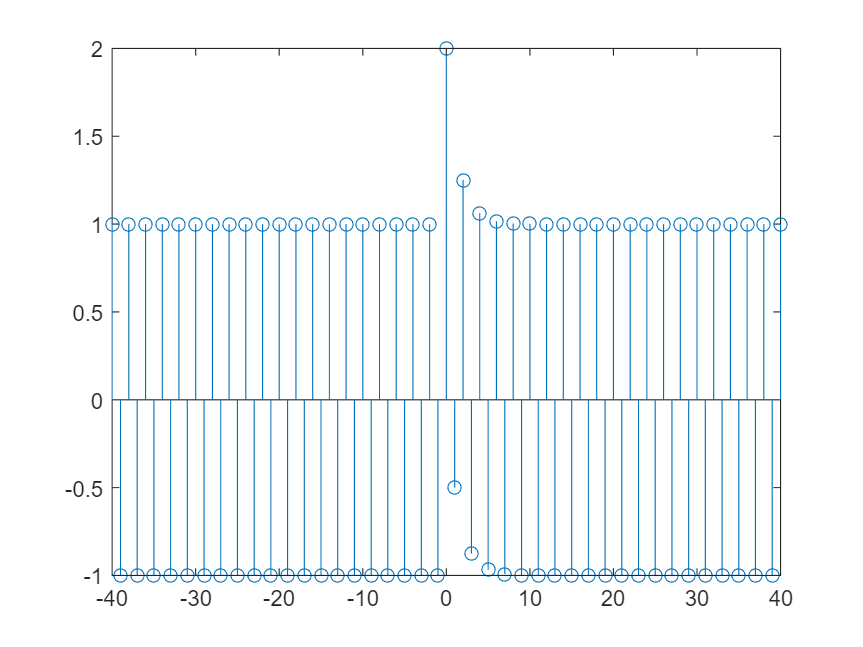

%(2)
z2=(-1).^k+(0.5).^k.*stepfun(k,0);
figure(6)
stem(k,z2)

clear;
clc;

#### 四、计算下列信号的卷积和，并画出结果

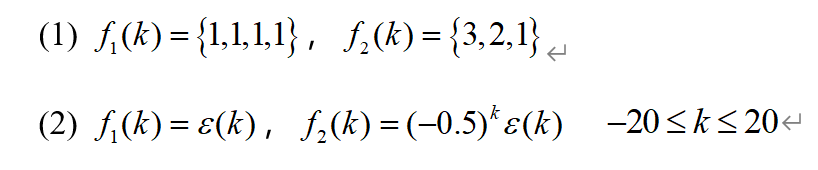

%(1)
f1=[1,1,1,1];
f2=[3,2,1];
result_1=conv(f1,f2);
disp("（1）的卷积和：");

（1）的卷积和：


disp(result_1);

     3     5     6     6     3     1



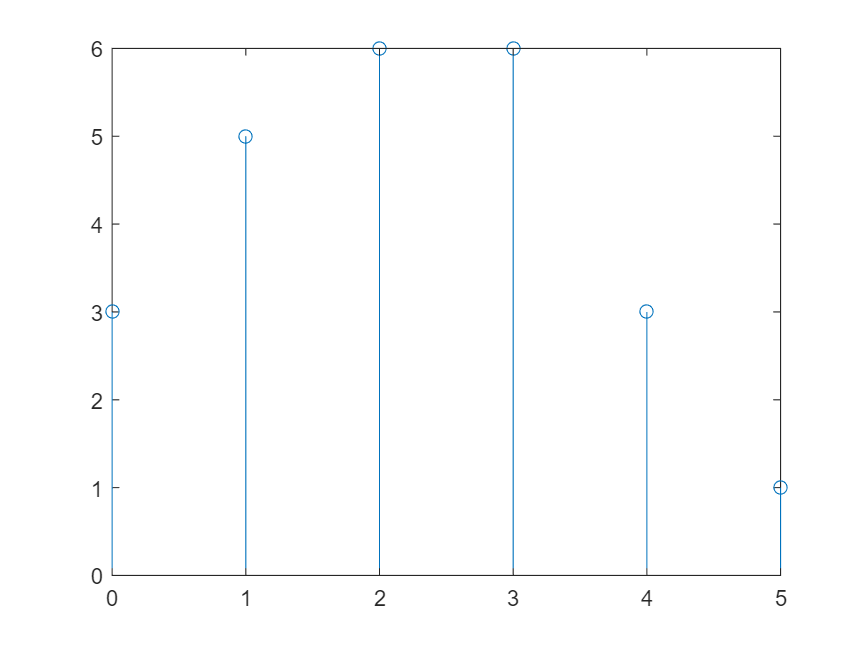

k=0:1:length(result_1)-1;
figure(7);
stem(k,result_1);

%(2)
k=-20:1:20;
f3=stepfun(k,0);
f4=(-0.5).^k.*stepfun(k,0);
result_2=conv(f3,f4);
disp("（2）的卷积和：");

（2）的卷积和：


disp(result_2);

  列 1 至 16

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

  列 17 至 32

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

  列 33 至 48

         0         0         0         0         0         0         0         0    1.0000    0.5000    0.7500    0.6250    0.6875    0.6562    0.6719    0.6641

  列 49 至 64

    0.6680    0.6660    0.6670    0.6665    0.6667    0.6666    0.6667    0.6667    0.6667    0.6667    0.6667    0.6667    0.6667   -0.3333    0.1667   -0.0833

  列 65 至 80

    0.0417   -0.0208    0.0104   -0.0052    0.0026   -0.0013    0.0007   -0.0003    0.0002   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000

  列 81

    0.0000



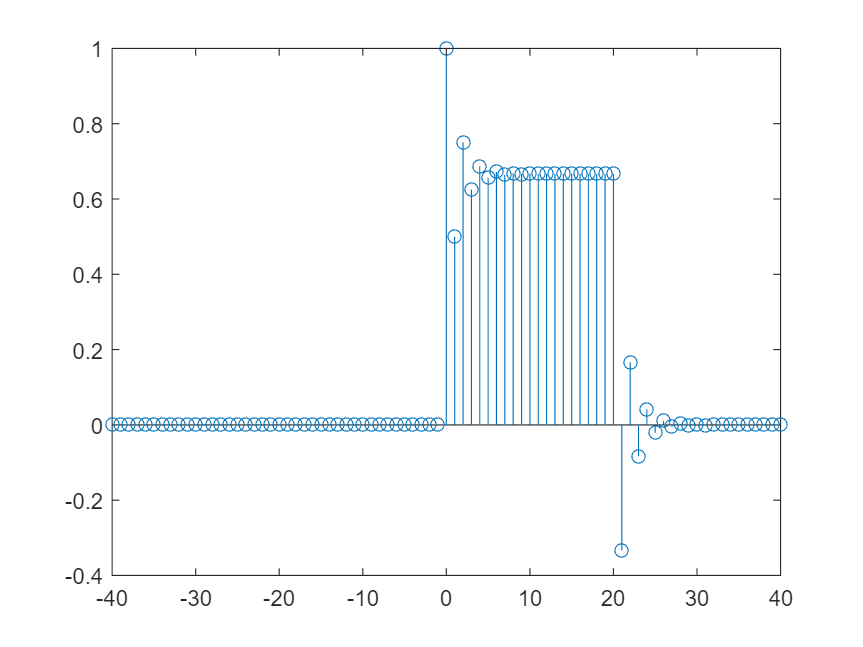

k=-40:1:length(result_2)-41;
figure(8);
stem(k,result_2);

clear;
clc;

#### 五、在同一坐标轴上绘制sin(t)/t、sin(2t)/2t和 sin(3t)/3t,要求采用不同的颜色、线型以及标记形状，*t*的取值范围为，间隔可取0.01。

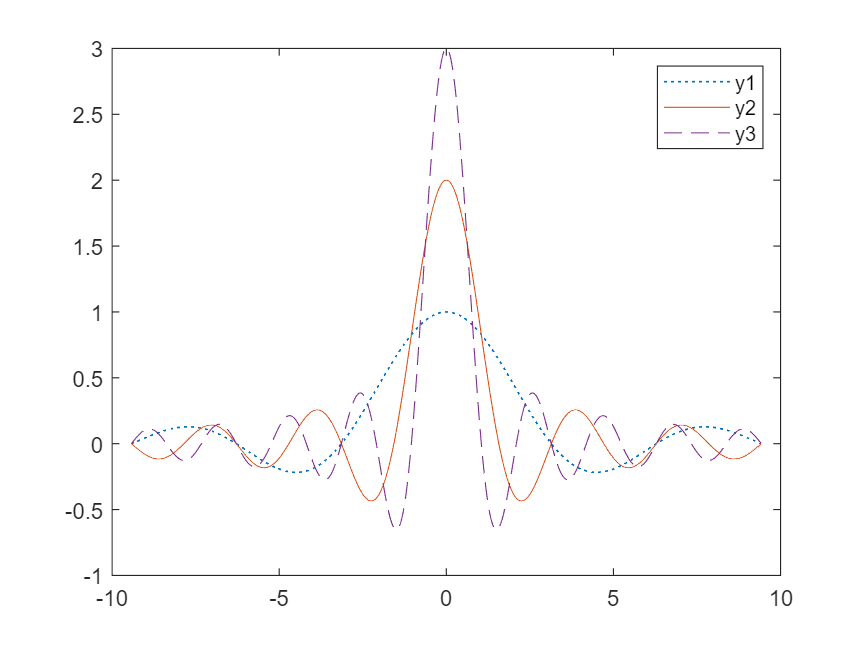

t=(-3.*pi):0.01:(3.*pi);
y1=sin(t)./t;
y2=sin(2.*t)./t;
y3=sin(3.*t)./t;
figure(9);
plot(t,y1,'Color',[0,0.447,0.741],'LineStyle',':','LineWidth',0.75);
hold on;
plot(t,y2,'Color',[0.85,0.325,0.098]);
hold on;
plot(t,y3,'Color',[0.494,0.184,0.556],'LineStyle','--');
hold off;
legend("y1","y2","y3");

clear;
clc;

#### 六、在[-5 5]时间范围内，以0.01为采样间隔，画出如下信号的时域波形，利用axis()函数设置横坐标和纵坐标范围分别为[-5 5]、[-1.2 1.2]；

#### 1)	阶跃信号 

#### 2)	频率为1Hz的三角脉冲信号（sawtooth函数）

#### 3)	频率为0.2Hz的方波信号（square函数）

#### 4)	频率为0.5 Hz的正弦信号。

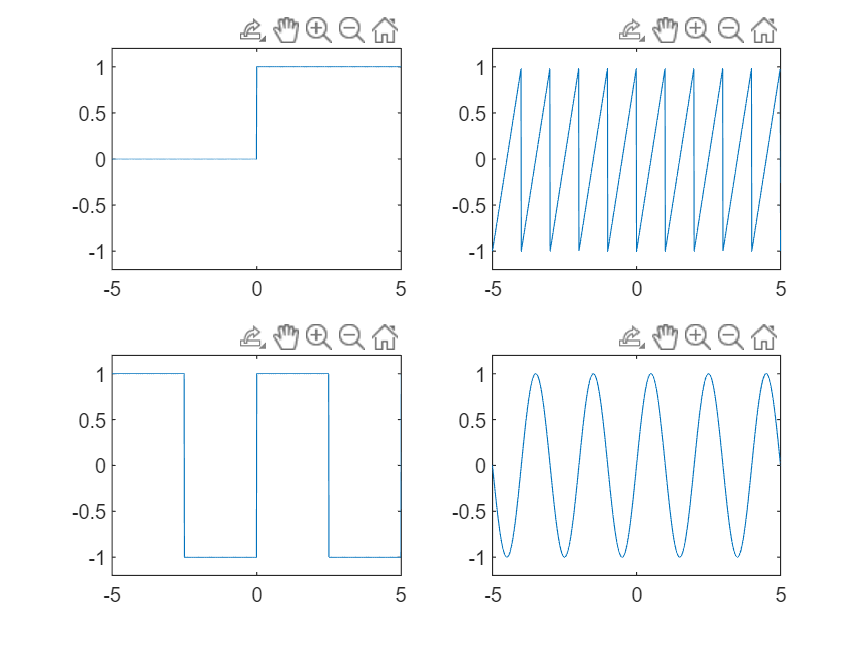

t=-5:0.01:5;
%(1)
f1=stepfun(t,0);
figure(10);
subplot(2,2,1);
plot(t,f1);
axis([-5,5,-1.2,1.2]);
%(2)
f2=sawtooth(2.*pi.*t);%频率1Hz
subplot(2,2,2);
plot(t,f2);
axis([-5,5,-1.2,1.2]);
%(3)
f3=square(0.4.*pi.*t);%频率0.2Hz
subplot(2,2,3);
plot(t,f3);
axis([-5,5,-1.2,1.2]);
%(4)
f4=sin(pi.*t);%频率0.5Hz
subplot(2,2,4);
plot(t,f4);
axis([-5,5,-1.2,1.2]);